# Data Processing - Discharge

- 기본적인 데이타를 검토하자

Age (Cycle number) 가 증가함에 따라 floating voltage 까지 충전하는데 시간이 더 걸린다 => 내부 저항의 증가 

floating voltage 이후에는 CV 로 충전으로 변경하는데 이때의 온도가 가장 높다. Age 가 증가함에 따라서 최고 온도 증가.

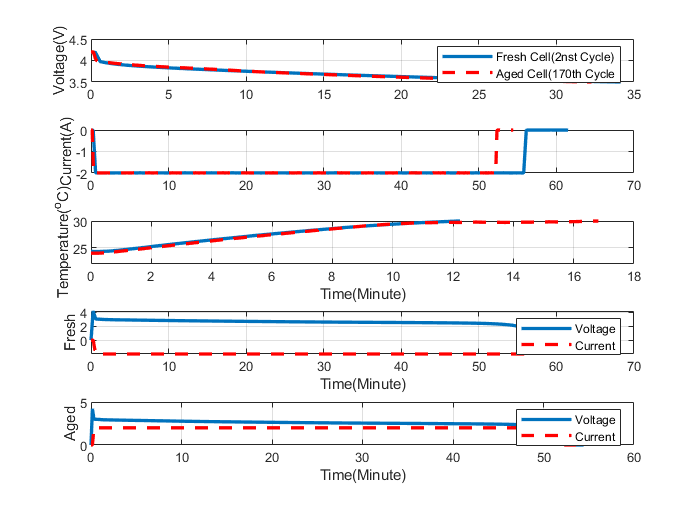

clear 
close all 

load B0005.mat
load B0006.mat
load B0007.mat
load B0018.mat
load B0033.mat
load B0034.mat
load B0036.mat

%%%%%% DisCharge

%Discharge
%constant current (CC) level of 2A 
%until the battery voltage fell to 2.7V, 2.5V, 2.2V and 2.5V for batteries 5 6 7 and 18 respectively. 

FDischargeTime = B0005.cycle(2).data.Time/60;
FreshCellDischarge_V = B0005.cycle(2).data.Voltage_measured;
FreshCellDischarge_I = B0005.cycle(2).data.Current_measured;
FreshCellDischarge_T = B0005.cycle(2).data.Temperature_measured;
FreshCellDischargeLoad_V = B0005.cycle(2).data.Voltage_load;
FreshCellDischargeLoad_I = B0005.cycle(2).data.Current_load;

ADiscargeTime = B0005.cycle(170).data.Time/60;
AgedCellDischarge_V = B0005.cycle(170).data.Voltage_measured;
AgedCellDischarge_I = B0005.cycle(170).data.Current_measured;
AgedCellDischarge_T = B0005.cycle(170).data.Temperature_measured;
AgedCellDischargeLoad_V = B0005.cycle(170).data.Voltage_load;
AgedCellDischargeLoad_I = B0005.cycle(170).data.Current_load;

%Voltage_measured: Battery terminal voltage (Volts)
%Current_measured: Battery output current (Amps)
%Temperature_measured: Battery temperature (degree C)
%Current_charge: Current measured at load (Amps)
%Voltage_charge: Voltage measured at load (Volts)
%Time: Time vector for the cycle (secs)
%Capacity: Battery capacity (Ahr) for discharge till 2.7V


figure(2)
subplot(511)
plot(FDischargeTime, FreshCellDischarge_V, 'linewidth', 2), hold on, plot(ADiscargeTime, AgedCellDischarge_V, 'r--','linewidth', 2)
hold off, legend('Fresh Cell(2nst Cycle)', 'Aged Cell(170th Cycle'), ylabel('Voltage(V)')
ylim([3.5 4.5]), grid on
subplot(512)
plot(FDischargeTime, FreshCellDischarge_I, 'linewidth', 2), hold on, plot(ADiscargeTime, AgedCellDischarge_I, 'r--', 'linewidth', 2)
hold off, ylabel('Current(A)'), grid on
% discharge till 2.7V   마이너스 값은 방전 의미
subplot(513)
plot(FDischargeTime, FreshCellDischarge_T, 'linewidth', 2), hold on, plot(ADiscargeTime, AgedCellDischarge_T, 'r--', 'linewidth', 2)
hold off, ylabel('Temperature(^oC)'), ylim([22 30]), grid on, xlabel Time(Minute)

subplot(514)
plot(FDischargeTime, FreshCellDischargeLoad_V, 'linewidth', 2), hold on, plot(FDischargeTime, FreshCellDischargeLoad_I, 'r--', 'linewidth', 2)
hold off, ylabel('Fresh'),legend('Voltage','Current'), grid on, xlabel Time(Minute)
% 충전기에 표시되는 전압 - CC 이후에 CV  
subplot(515)
plot(ADiscargeTime, AgedCellDischargeLoad_V, 'linewidth', 2), hold on, plot(ADiscargeTime, AgedCellDischargeLoad_I, 'r--', 'linewidth', 2)
hold off, ylabel('Aged'),legend('Voltage','Current'), grid on, xlabel Time(Minute)


% FTime 과 ATime의 크기는 다르다.
size(B0005.cycle(1).data.Voltage_measured,2)

ans = 789

size(B0005.cycle(168).data.Voltage_measured,2)

ans = 3598

size(B0005.cycle)

ans =      1   616


size(B0005.cycle,1)

ans = 1

size(B0005.cycle,2)

ans = 616

### 방전 전압

%%%%%%%%%%%%%%% discharge
figure
%newcolors = {'#F00','#F80','#FF0','#0B0','#00F','#50F','#A0F'};
%colororder(newcolors)

hold on
items = size(B0005.cycle,2)

items = 616

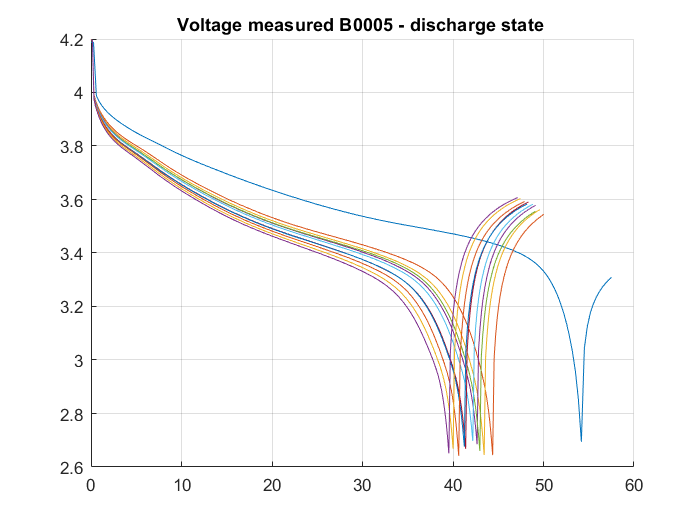

%marker = ['-','--',':','-.','-o','--o',':o','-.o','+',"*"]

for i=1:items
    if isequal(B0005.cycle(i).type, 'discharge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0005.cycle(i).data.Time/60,B0005.cycle(i).data.Voltage_measured)
        end
    end
end
hold off 
title("Voltage measured B0005 - discharge state ")
grid on

figure
hold on
items = size(B0006.cycle,2)

items = 616

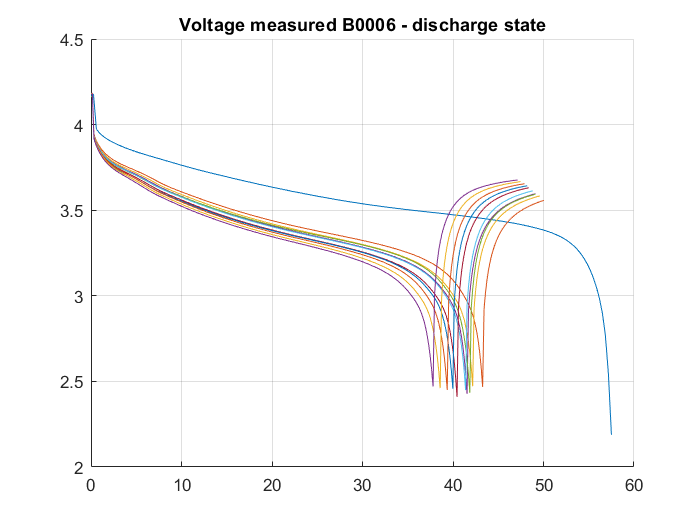

for i=1:items
    if isequal(B0006.cycle(i).type, 'discharge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0006.cycle(i).data.Time/60,B0006.cycle(i).data.Voltage_measured)
        end
    end
end
hold off 
title("Voltage measured B0006 - discharge state")
grid on


figure
hold on
items = size(B0007.cycle,2)

items = 616

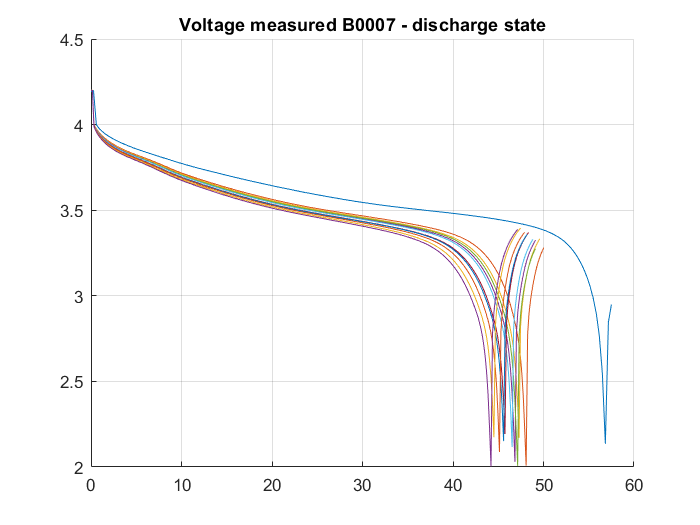

for i=1:items
    if isequal(B0007.cycle(i).type, 'discharge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0007.cycle(i).data.Time/60,B0007.cycle(i).data.Voltage_measured)
        end
    end
end
hold off 
title("Voltage measured B0007 - discharge state")
grid on


figure
hold on
items = size(B0018.cycle,2)

items = 319

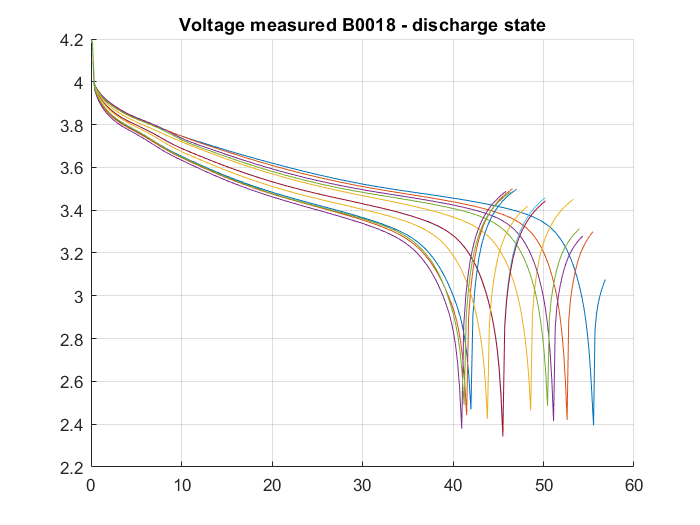

for i=1:items
    if isequal(B0018.cycle(i).type, 'discharge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0018.cycle(i).data.Time/60,B0018.cycle(i).data.Voltage_measured)
        end
    end
end
hold off 
title("Voltage measured B0018 - discharge state")
grid on


figure
hold on
items = size(B0036.cycle,2)

items = 486

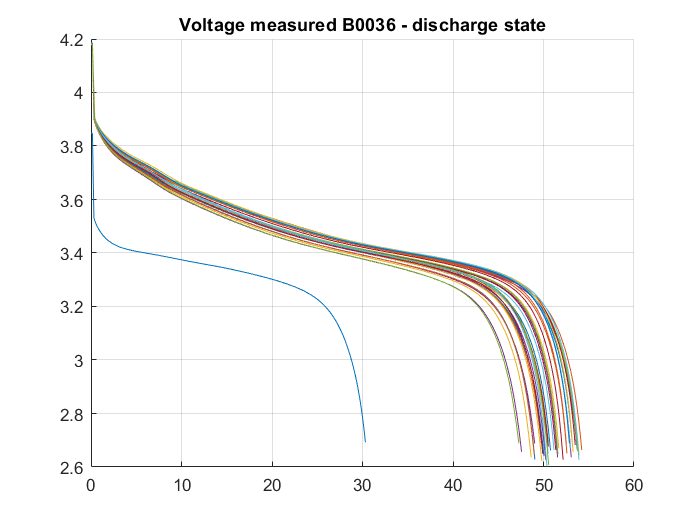

for i=1:items
    if isequal(B0036.cycle(i).type, 'discharge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0036.cycle(i).data.Time/60,B0036.cycle(i).data.Voltage_measured)
        end
    end
end
hold off 
title("Voltage measured B0036 - discharge state")
grid on


figure
hold on
items = size(B0033.cycle,2)

items = 486

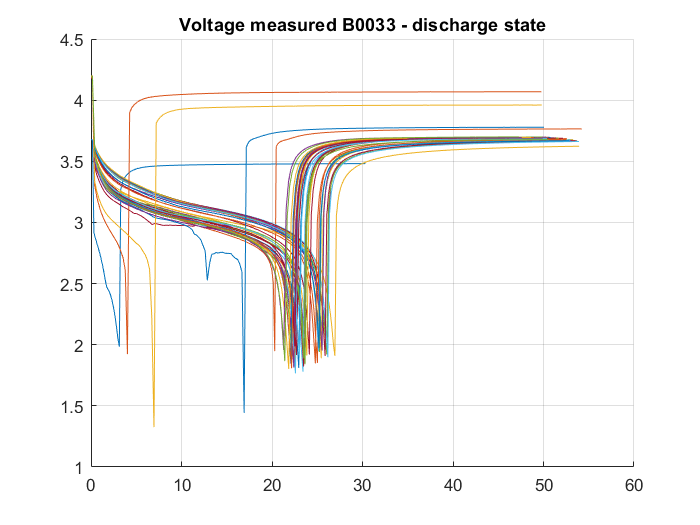

for i=1:items
    if isequal(B0033.cycle(i).type, 'discharge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0033.cycle(i).data.Time/60,B0033.cycle(i).data.Voltage_measured)
        end
    end
end
hold off 
title("Voltage measured B0033 - discharge state")
grid on


figure
hold on
items = size(B0034.cycle,2)

items = 486

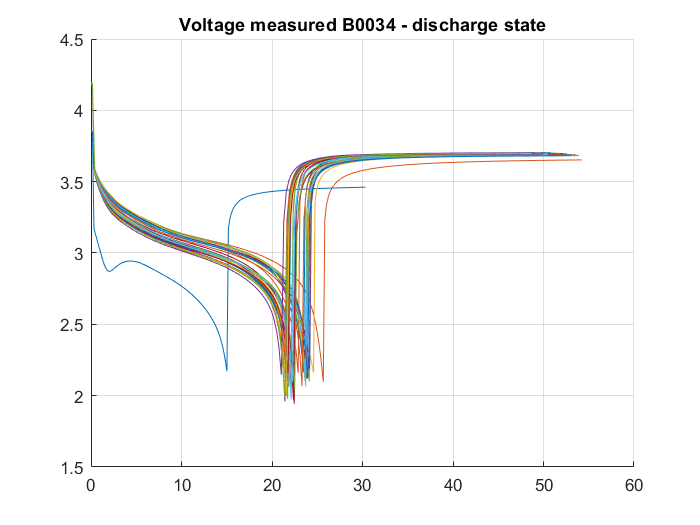

for i=1:items
    if isequal(B0034.cycle(i).type, 'discharge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0034.cycle(i).data.Time/60,B0034.cycle(i).data.Voltage_measured)
        end
    end
end
hold off 
title("Voltage measured B0034 - discharge state")
grid on


figure
hold on
items = size(B0036.cycle,2)

items = 486

for i=1:items
    if isequal(B0036.cycle(i).type, 'discharge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0036.cycle(i).data.Time/60,B0036.cycle(i).data.Voltage_measured)
        end
    end
end
hold off 
title("Voltage measured B0036 - discharge state")
grid on


discVoltageIndex = 10

discVoltageIndex = 10

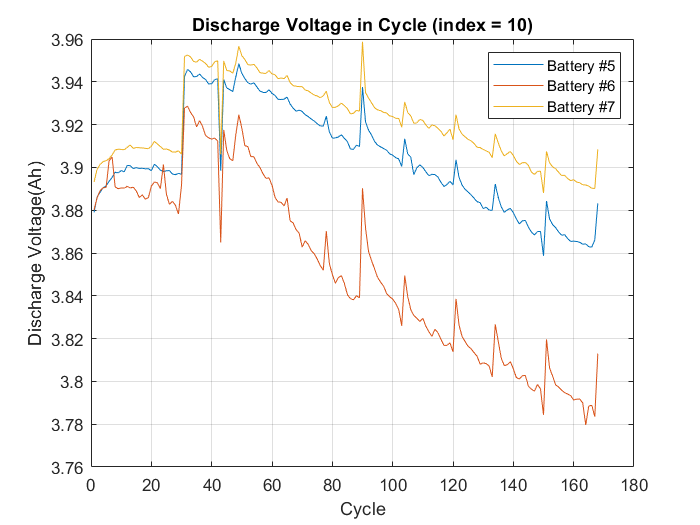

discVoltage5 = extract_discharge_voltage_by_index(B0005,discVoltageIndex);
discVoltage6 = extract_discharge_voltage_by_index(B0006,discVoltageIndex);
discVoltage7 = extract_discharge_voltage_by_index(B0007,discVoltageIndex);
figure
plot(discVoltage5), hold on, plot(discVoltage6), plot(discVoltage7)
hold off, grid on
xlabel Cycle, ylabel('Discharge Voltage(Ah)')
% ,num2str(discVoltageIndex))
legend('Battery #5', 'Battery #6', 'Battery #7')
title('Discharge Voltage in Cycle (index = 10)')

### 방전전류

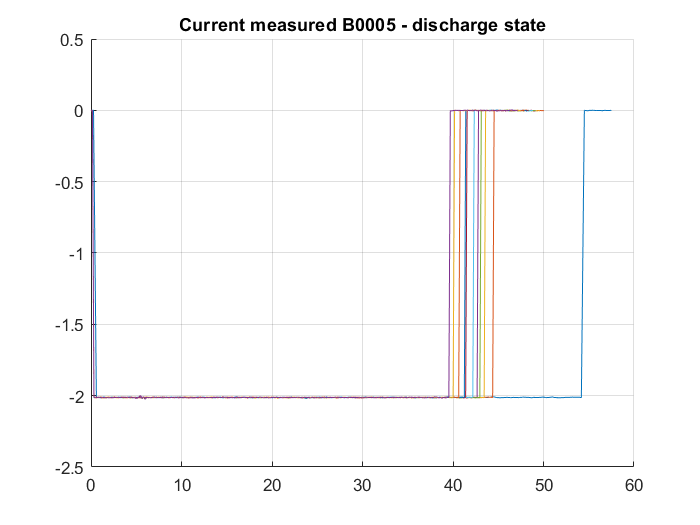


figure
hold on
items = size(B0005.cycle,2);
for i=1:items
    if isequal(B0005.cycle(i).type, 'discharge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0005.cycle(i).data.Time/60,B0005.cycle(i).data.Current_measured)
        end
    end
end
hold off 
title("Current measured B0005 - discharge state")
grid on

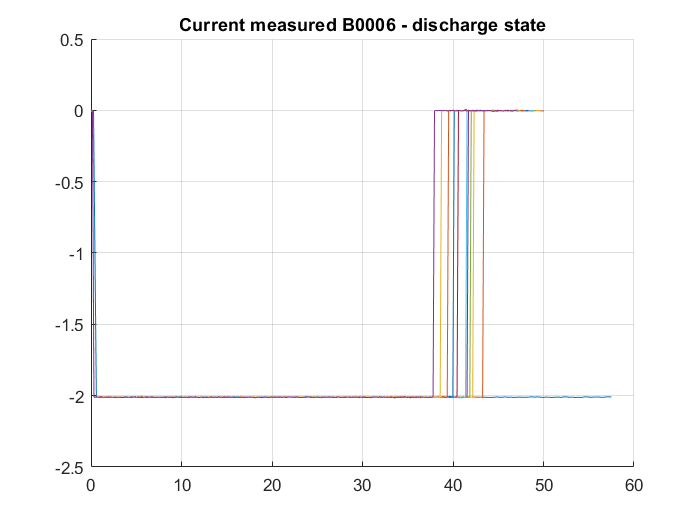


figure
hold on
items = size(B0006.cycle,2);
for i=1:items
    if isequal(B0006.cycle(i).type, 'discharge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0006.cycle(i).data.Time/60,B0006.cycle(i).data.Current_measured)
        end
    end
end
hold off 
title("Current measured B0006 - discharge state")
grid on

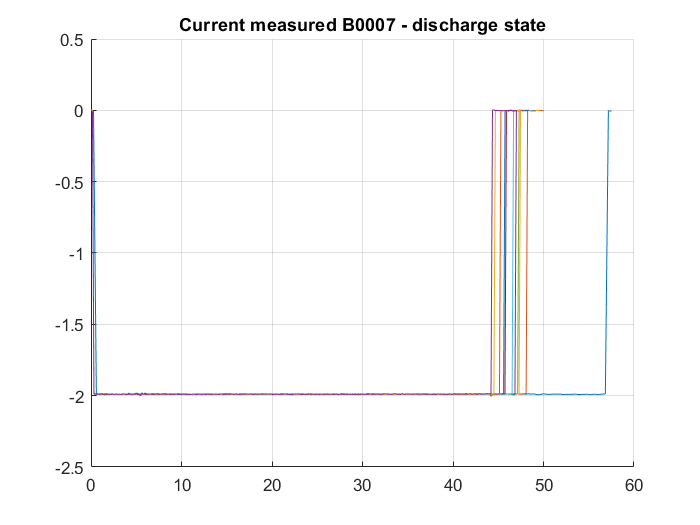


figure
hold on
items = size(B0007.cycle,2);
for i=1:items
    if isequal(B0007.cycle(i).type, 'discharge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0007.cycle(i).data.Time/60,B0007.cycle(i).data.Current_measured)
        end
    end
end
hold off 
title("Current measured B0007 - discharge state")
grid on

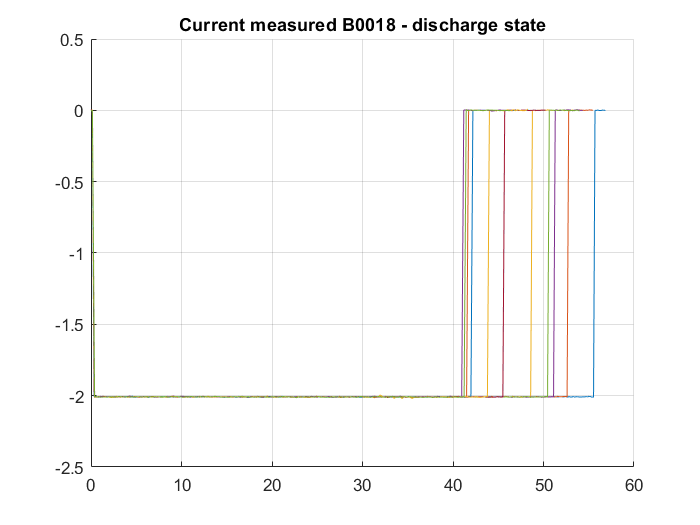


figure
hold on
items = size(B0018.cycle,2);
for i=1:items
    if isequal(B0018.cycle(i).type, 'discharge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0018.cycle(i).data.Time/60,B0018.cycle(i).data.Current_measured)
        end
    end
end
hold off 
title("Current measured B0018 - discharge state")
grid on

### 방전온도

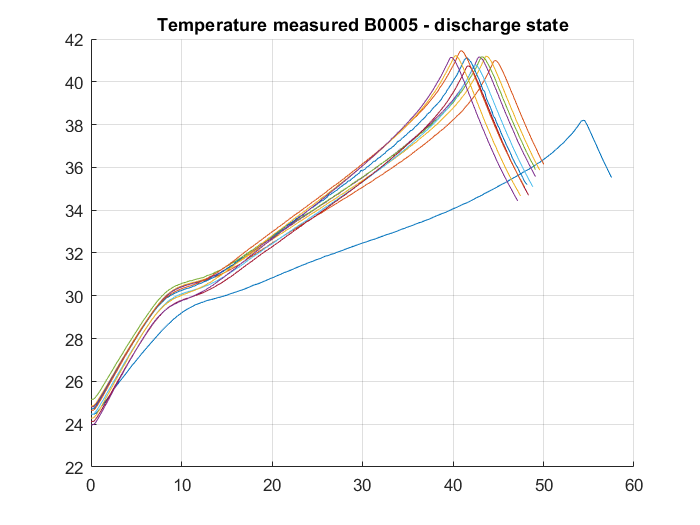

figure
hold on
items = size(B0005.cycle,2);
for i=1:items
    if isequal(B0005.cycle(i).type, 'discharge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0005.cycle(i).data.Time/60,B0005.cycle(i).data.Temperature_measured)
        end
    end
end
hold off 
title("Temperature measured B0005 - discharge state")
grid on

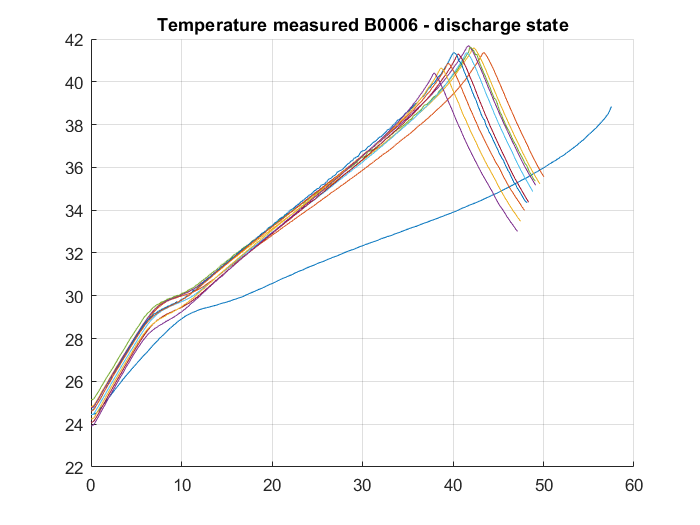


figure
hold on
items = size(B0006.cycle,2);
for i=1:items
    if isequal(B0006.cycle(i).type, 'discharge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0006.cycle(i).data.Time/60,B0006.cycle(i).data.Temperature_measured)
        end
    end
end
hold off 
title("Temperature measured B0006 - discharge state")
grid on

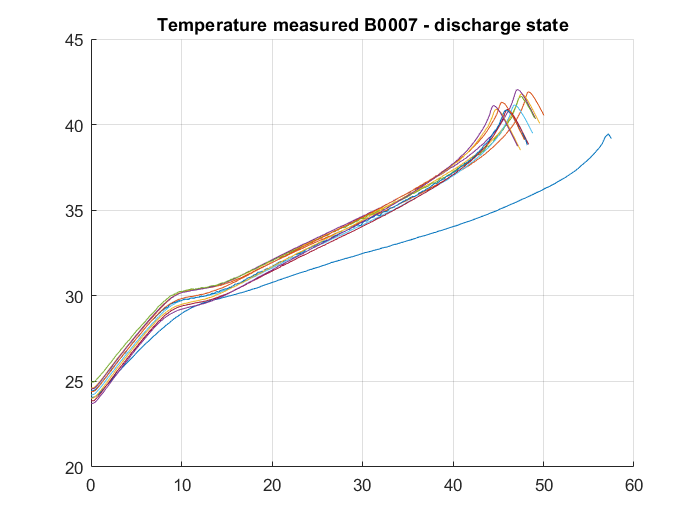


figure
hold on
items = size(B0007.cycle,2);
for i=1:items
    if isequal(B0007.cycle(i).type, 'discharge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0007.cycle(i).data.Time/60,B0007.cycle(i).data.Temperature_measured)
        end
    end
end
hold off 
title("Temperature measured B0007 - discharge state")
grid on

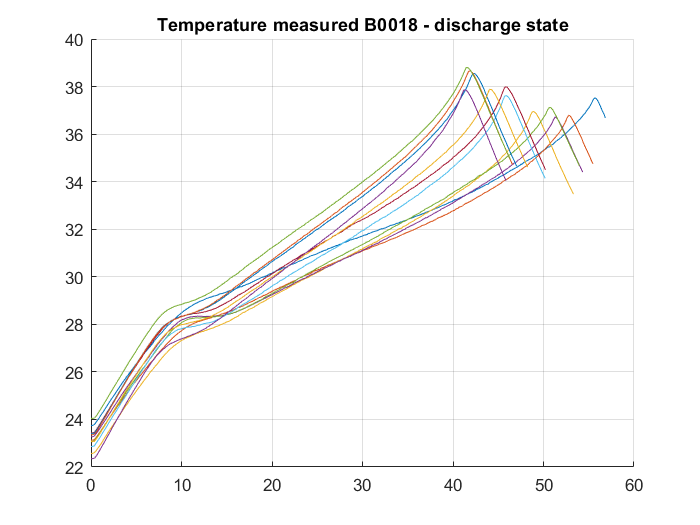


figure
hold on
items = size(B0018.cycle,2);
for i=1:items
    if isequal(B0018.cycle(i).type, 'discharge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0018.cycle(i).data.Time/60,B0018.cycle(i).data.Temperature_measured)
        end
    end
end
hold off 
title("Temperature measured B0018 - discharge state")
grid on

### 측정 내부저항

impedance the fields are: 

Sense_current: Current in sense branch (Amps) 

Battery_current: Current in battery branch (Amps) 

Current_ratio: Ratio of the above currents 

Battery_impedance: Battery impedance (Ohms) computed from raw data 

Rectified_impedance: Calibrated and smoothed battery impedance(Ohms) 

**Re: Estimated electrolyte resistance(Ohms) <= ohm 저항 = 수명과 관련 **

Rct: Estimated charge transfer resistance(Ohms) <= 충전 상태와 관련 

비슷한 실험방법으로 측정해 보았다.

뒤쪽으로 선형성을 보이나 앞쪽에서 비선형성이 보여서 사용하기는 어려울 것 같다.

%%%%%%%%%%%%%%% calculate ohm by Voltage and current 

items = size(B0005.cycle,2)

items = 616

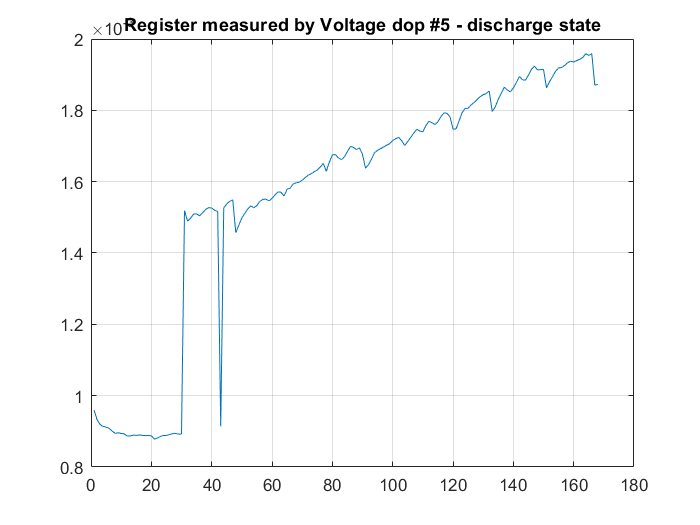

ohm_index=1;
deltaVoltages = [];
ohm = [];
Ifirst3 = 2; % 2A CC load
Vfirst3 = 4.2;
indexV = []; 
start_index = 1;
measure_index = 10;
for i=1:items
    if isequal(B0005.cycle(i).type, 'discharge')
        deltaV = B0005.cycle(i).data.Voltage_measured(start_index) -  B0005.cycle(i).data.Voltage_measured(measure_index);
        deltaT = B0005.cycle(i).data.Time(measure_index) - B0005.cycle(i).data.Time(start_index);
        
        % deltaV = Vfirst3 -  B0005.cycle(i).data.Voltage_measured(measure_index);
        % deltaT = B0005.cycle(i).data.Time(measure_index) ;
        
        %B0005.cycle(i).data.Voltage_measured(1)
        deltaVoltages(ohm_index) =  deltaV;
        ohm(ohm_index) = deltaV / (deltaT * Ifirst3 );
        indexV(ohm_index)=i;
        
        ohm_index=ohm_index+1;
    end
end
ohm5 = ohm;
figure
plot(ohm)

title("Register measured by Voltage dop #5 - discharge state")
% 앞부분이 이상한 데이타가 있다
grid on



items = size(B0006.cycle,2)

items = 616

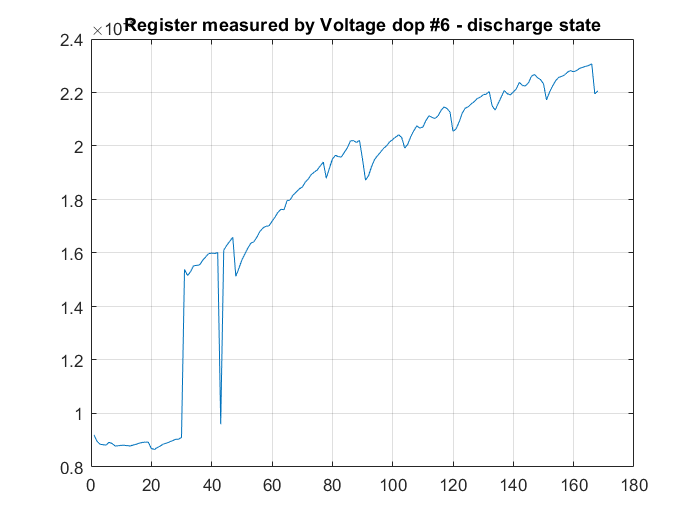

ohm_index=1;
deltaVoltages = [];
ohm = [];
Ifirst3 = 2; % 2A CC load
Vfirst3 = 4.2;
indexV = []; 
start_index = 1;
measure_index = 10;
for i=1:items
    if isequal(B0006.cycle(i).type, 'discharge')
        deltaV = B0006.cycle(i).data.Voltage_measured(start_index) -  B0006.cycle(i).data.Voltage_measured(measure_index);
        deltaT = B0006.cycle(i).data.Time(measure_index) - B0006.cycle(i).data.Time(start_index);
        
        % deltaV = Vfirst3 -  B0006.cycle(i).data.Voltage_measured(measure_index);
        % deltaT = B0006.cycle(i).data.Time(measure_index) ;
        
        %B0006.cycle(i).data.Voltage_measured(1)
        deltaVoltages(ohm_index) =  deltaV;
        ohm(ohm_index) = deltaV / (deltaT * Ifirst3 );
        indexV(ohm_index)=i;
        
        ohm_index=ohm_index+1;
    end
end
ohm6 = ohm;
figure
plot(ohm)


title("Register measured by Voltage dop #6 - discharge state")
% 앞부분이 이상한 데이타가 있다
grid on


items = size(B0007.cycle,2)

items = 616

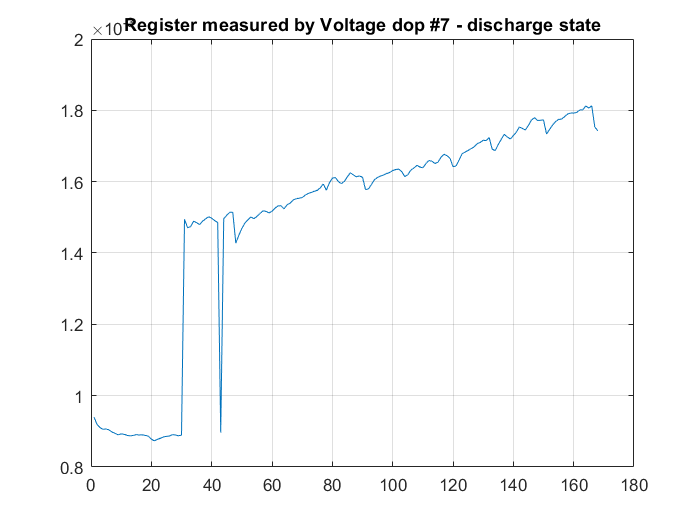

ohm_index=1;
deltaVoltages = [];
ohm = [];
Ifirst3 = 2; % 2A CC load
Vfirst3 = 4.2;
indexV = []; 
start_index = 1;
measure_index = 10;
for i=1:items
    if isequal(B0007.cycle(i).type, 'discharge')
        deltaV = B0007.cycle(i).data.Voltage_measured(start_index) -  B0007.cycle(i).data.Voltage_measured(measure_index);
        deltaT = B0007.cycle(i).data.Time(measure_index) - B0007.cycle(i).data.Time(start_index);
        
        % deltaV = Vfirst3 -  B0007.cycle(i).data.Voltage_measured(measure_index);
        % deltaT = B0007.cycle(i).data.Time(measure_index) ;
        
        %B0007.cycle(i).data.Voltage_measured(1)
        deltaVoltages(ohm_index) =  deltaV;
        ohm(ohm_index) = deltaV / (deltaT * Ifirst3 );
        indexV(ohm_index)=i;
        
        ohm_index=ohm_index+1;
    end
end
ohm7 = ohm;
figure
plot(ohm)

title("Register measured by Voltage dop #7 - discharge state")
% 앞부분이 이상한 데이타가 있다
grid on


items = size(B0018.cycle,2)

items = 319

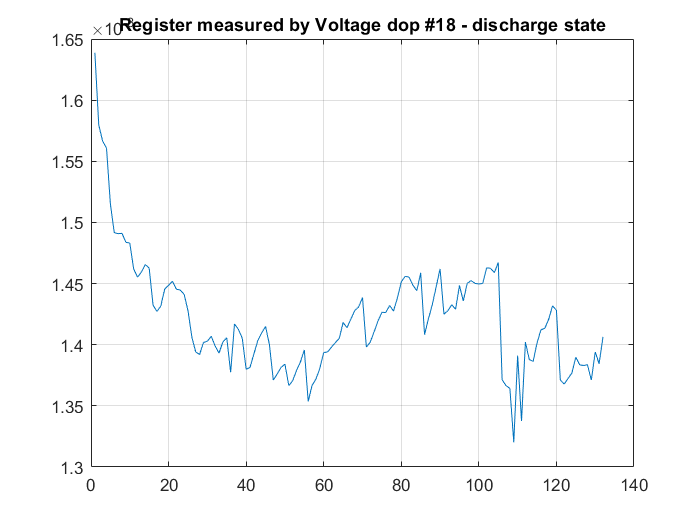

ohm_index=1;
deltaVoltages = [];
ohm = [];
Ifirst3 = 2; % 2A CC load
Vfirst3 = 4.2;
indexV = []; 
start_index = 1;
measure_index = 10;
for i=1:items
    if isequal(B0018.cycle(i).type, 'discharge')
        deltaV = B0018.cycle(i).data.Voltage_measured(start_index) -  B0018.cycle(i).data.Voltage_measured(measure_index);
        deltaT = B0018.cycle(i).data.Time(measure_index) - B0018.cycle(i).data.Time(start_index);
        
        % deltaV = Vfirst3 -  B0018.cycle(i).data.Voltage_measured(measure_index);
        % deltaT = B0018.cycle(i).data.Time(measure_index) ;
        
        %B0018.cycle(i).data.Voltage_measured(1)
        deltaVoltages(ohm_index) =  deltaV;
        ohm(ohm_index) = deltaV / (deltaT * Ifirst3 );
        indexV(ohm_index)=i;
        
        ohm_index=ohm_index+1;
    end
end
ohm18 = ohm;
figure
plot(ohm)

title("Register measured by Voltage dop #18 - discharge state")
% 앞부분이 이상한 데이타가 있다
grid on


items = size(B0036.cycle,2)

items = 486

ohm_index=1;
deltaVoltages = [];
ohm = [];
Ifirst3 = 2; % 2A CC load
Vfirst3 = 4.2;
indexV = []; 
start_index = 1;
B0036

B0036 = struct with fields:
    cycle: [1×486 struct]


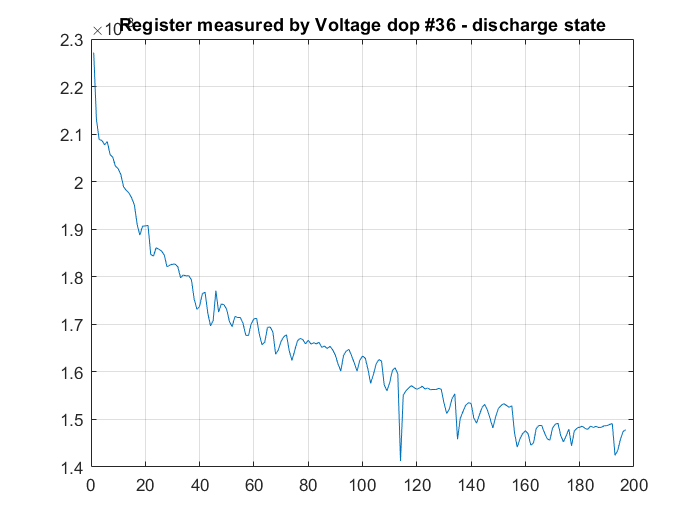

for i=1:items
    if isequal(B0036.cycle(i).type, 'discharge')
        deltaV = B0036.cycle(i).data.Voltage_measured(start_index) -  B0036.cycle(i).data.Voltage_measured(measure_index);
        deltaT = B0036.cycle(i).data.Time(measure_index) - B0036.cycle(i).data.Time(start_index);
        
        % deltaV = Vfirst3 -  B0036.cycle(i).data.Voltage_measured(measure_index);
        % deltaT = B0036.cycle(i).data.Time(measure_index) ;
        
        %B0036.cycle(i).data.Voltage_measured(1)
        deltaVoltages(ohm_index) =  deltaV;
        ohm(ohm_index) = deltaV / (deltaT * Ifirst3 );
        indexV(ohm_index)=i;
        
        ohm_index=ohm_index+1;
    end
end
ohm36 = ohm;
figure
plot(ohm36)

title("Register measured by Voltage dop #36 - discharge state")
% 앞부분이 이상한 데이타가 있다
grid on

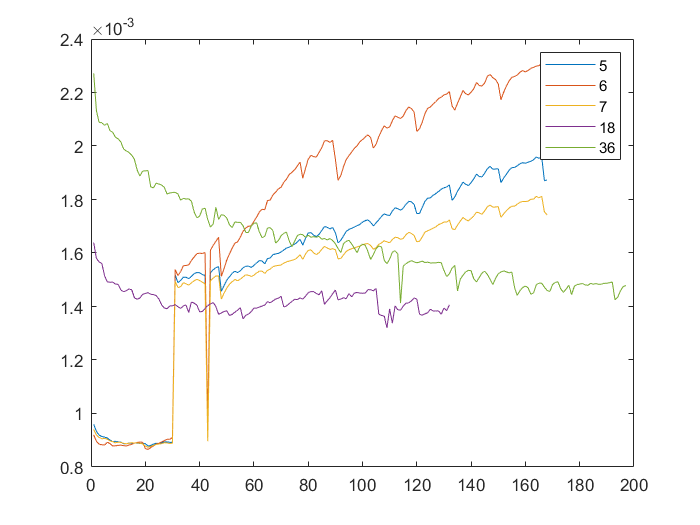




figure
plot(ohm5), hold on,plot(ohm6),plot(ohm7),plot(ohm18),plot(ohm36)
legend('5','6','7','18','36')

NASA 데이타에서 EIS 로 측정된 데이타를 사용하는 경우

실제 데이타가 선형이 아니라서 바로 이용하기는 힘들것 같다.

테스트가 잘못된건지 아무래도 모르겠다.

따라서 내부저항을 확인하기 위해서는 보다 선형적인 다른 dataset 을 찾아야 할 것 같다.

items = size(B0033.cycle,2)

items = 486

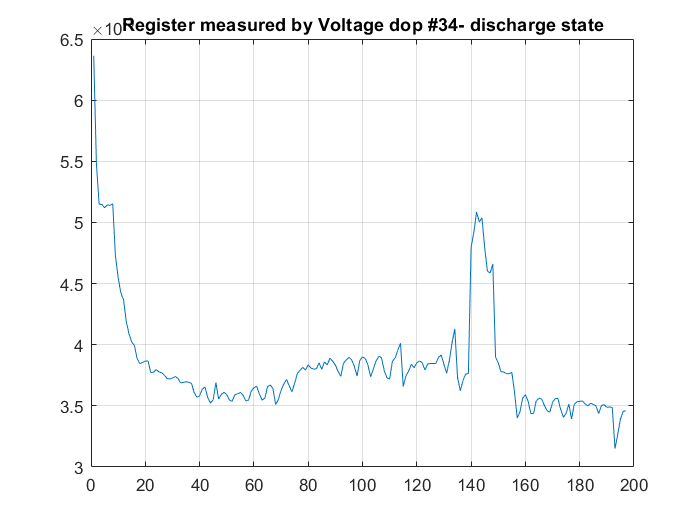

ohm_index=1;
deltaVoltages = [];
ohm = [];
Ifirst3 = 2; % 2A CC load
Vfirst3 = 4.2;
indexV = []; 
start_index = 1;
measure_index = 10;
for i=1:items
    if isequal(B0033.cycle(i).type, 'discharge')
        deltaV = B0033.cycle(i).data.Voltage_measured(start_index) -  B0033.cycle(i).data.Voltage_measured(measure_index);
        deltaT = B0033.cycle(i).data.Time(measure_index) - B0033.cycle(i).data.Time(start_index);
        
        % deltaV = Vfirst3 -  B0033.cycle(i).data.Voltage_measured(measure_index);
        % deltaT = B0033.cycle(i).data.Time(measure_index) ;
        
        %B0033.cycle(i).data.Voltage_measured(1)
        deltaVoltages(ohm_index) =  deltaV;
        ohm(ohm_index) = deltaV / (deltaT * Ifirst3 );
        indexV(ohm_index)=i;
        
        ohm_index=ohm_index+1;
    end
end
ohm33 = ohm;
figure
plot(ohm)

title("Register measured by Voltage dop #34- discharge state")
% 앞부분이 이상한 데이타가 있다
grid on


items = size(B0034.cycle,2)

items = 486

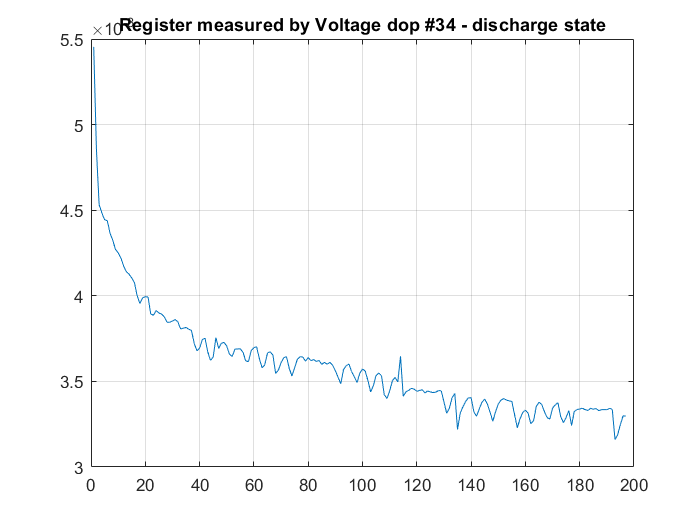

ohm_index=1;
deltaVoltages = [];
ohm = [];
Ifirst3 = 2; % 2A CC load
Vfirst3 = 4.2;
indexV = []; 
start_index = 1;
measure_index = 10;
for i=1:items
    if isequal(B0034.cycle(i).type, 'discharge')
        deltaV = B0034.cycle(i).data.Voltage_measured(start_index) -  B0034.cycle(i).data.Voltage_measured(measure_index);
        deltaT = B0034.cycle(i).data.Time(measure_index) - B0034.cycle(i).data.Time(start_index);
        
        % deltaV = Vfirst3 -  B0034.cycle(i).data.Voltage_measured(measure_index);
        % deltaT = B0034.cycle(i).data.Time(measure_index) ;
        
        %B0034.cycle(i).data.Voltage_measured(1)
        deltaVoltages(ohm_index) =  deltaV;
        ohm(ohm_index) = deltaV / (deltaT * Ifirst3 );
        indexV(ohm_index)=i;
        
        ohm_index=ohm_index+1;
    end
end
ohm34 = ohm;
figure
plot(ohm)

title("Register measured by Voltage dop #34 - discharge state")
% 앞부분이 이상한 데이타가 있다
grid on


items = size(B0036.cycle,2)

items = 486

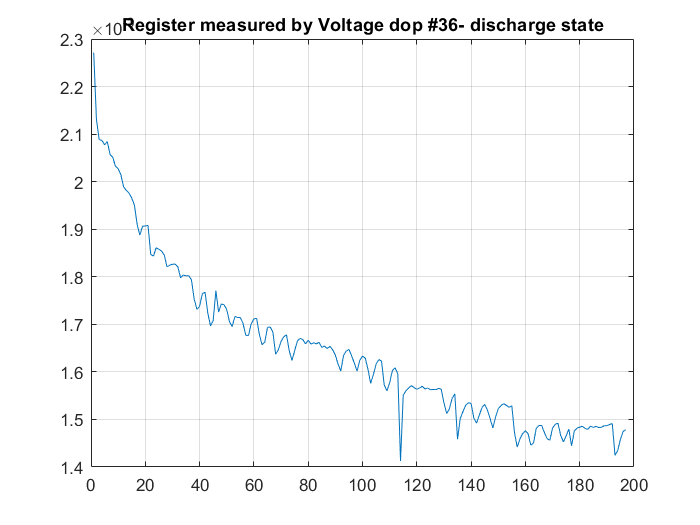

ohm_index=1;
deltaVoltages = [];
ohm = [];
Ifirst3 = 2; % 2A CC load
Vfirst3 = 4.2;
indexV = []; 
start_index = 1;
measure_index = 10;
for i=1:items
    if isequal(B0036.cycle(i).type, 'discharge')
        deltaV = B0036.cycle(i).data.Voltage_measured(start_index) -  B0036.cycle(i).data.Voltage_measured(measure_index);
        deltaT = B0036.cycle(i).data.Time(measure_index) - B0036.cycle(i).data.Time(start_index);
        
        % deltaV = Vfirst3 -  B0036.cycle(i).data.Voltage_measured(measure_index);
        % deltaT = B0036.cycle(i).data.Time(measure_index) ;
        
        %B0036.cycle(i).data.Voltage_measured(1)
        deltaVoltages(ohm_index) =  deltaV;
        ohm(ohm_index) = deltaV / (deltaT * Ifirst3 );
        indexV(ohm_index)=i;
        
        ohm_index=ohm_index+1;
    end
end
ohm36 = ohm;
figure
plot(ohm)

title("Register measured by Voltage dop #36- discharge state")
% 앞부분이 이상한 데이타가 있다
grid on

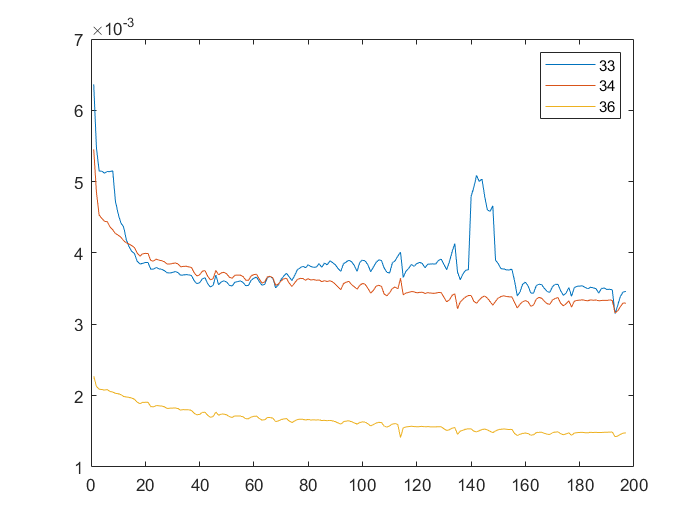




figure
plot(ohm33), hold on,plot(ohm34),plot(ohm36)
legend('33','34','36')